# Sensing System - revB

Changes since previous version:

- Implemented the ability to compute the frame rate and to predict when the next frame will occur

- Pre-allocating memory where possible

- converting established operations to functions

To-Do's:

- Need to find a way to package all of the one-off variables into at least a struct of some type so as to not crowd the workspace too much

Bugs Caught and Changes Made

- Implemented a "debugger" module to track key characteristics 

- line 144 (moved the following if-else statement to be before the code that resets the received_samples_left, received_sample_index, and frame_samples_left code): if received_samples_left ~= max_received_sample_index

- line 208 changed to: reshaped_signal = reshape(received_signal,[],spectogram_params.num_freq_spectrum_samples_per_spectogram); so that it now correctly reshapes the incomming signal

- line 227 changed to: plot_params.times = 0: spectogram_params.freq_sampling_period_us : spectogram_params.num_freq_spectrum_samples_per_spectogram * spectogram_params.freq_sampling_period_us - spectogram_params.freq_sampling_period_us; (was missing spectogram_params.num_freq_spectrum_samples_per_spectogram * spectogram_params.freq_sampling_period_us because previous freq sampling period was 1us) 

- line 263 changed to: plot_params.combined_spectogram_times = 0: spectogram_params.freq_sampling_period_us : 2 * spectogram_params.num_freq_spectrum_samples_per_spectogram * spectogram_params.freq_sampling_period_us - spectogram_params.freq_sampling_period_us; (was missing same thing as previous comment)

- line 272 chaned to: [idx,corepts] = dbscan([detected_times.',detected_frequencies.'],5,2); (revised the computation of db scan to be from array indicies to the actual detected times and frequencies in an effort to make it a more flexible calculation)

New Configuration being used:

- Spectogram fft size = 64 bins

- Spectogram frequency sampling period: 2us

- num_freq_spectrum_samples_per_spectogram: 25

- Threshold number of points for a valid detected chirp: 5

- Added a timing offset to the spectrogram parameters

## Assumptions/Settings

Chirp Parameters:

- cycle period: 50 us

- idle time: 30 us

- slope: 1 MHz/us

- BW: 20 MHz

- SDR sampling rate: 50 Msps

"Spectogram Settings"

- fft size: 32 bin

- frequency sampling period: 1us (sampled every us)

## Defining the "victim" parameters that the sensing module will sense

%configure chirp parameters
victim.chirp_params.cycle_period_us = 20.32;
victim.chirp_params.slope_MHz_us = 1.24;
victim.chirp_params.BW_MHz = 20;                   %the bandwidth will be close to this but may not be exactly this
victim.chirp_params.FMCW_sample_rate_Msps = 50;
victim.chirp_params.ramp_end_time_us = ceil(victim.chirp_params.BW_MHz / victim.chirp_params.slope_MHz_us);
victim.chirp_params.BW_MHz = victim.chirp_params.ramp_end_time_us * victim.chirp_params.slope_MHz_us;
victim.chirp_params.idle_time_us = victim.chirp_params.cycle_period_us - victim.chirp_params.ramp_end_time_us;
victim.chirp_params.num_samples_idle_time = int32(victim.chirp_params.idle_time_us * victim.chirp_params.FMCW_sample_rate_Msps);

%configure frame parameters
frames_to_compute = 10;
victim.frame_params.num_chirps = 32;
victim.frame_params.cycle_time_ms = 33.000020; %trying to determine the frame rate to within 0.02 us just like the chirp rate
victim.frame_params.active_frame_time_ms = victim.chirp_params.cycle_period_us * victim.frame_params.num_chirps * 1e-3;
victim.frame_params.num_samples_per_frame = int32(victim.frame_params.cycle_time_ms * 1e3 * victim.chirp_params.FMCW_sample_rate_Msps);


%configure waveform parameters
victim.waveform_params.sample_rate_Hz = victim.chirp_params.FMCW_sample_rate_Msps * 1e6;
victim.waveform_params.sweep_time_s = victim.chirp_params.ramp_end_time_us * 1e-6;
victim.waveform_params.sweep_BW_Hz = victim.chirp_params.BW_MHz * 1e6;
victim.waveform_params.sweep_interval = 'Positive';
victim.waveform_params.sweep_direction = 'Up';
victim.waveform_params.output_format = 'Sweeps';
victim.waveform_params.num_sweeps = 1;

victim.waveform = phased.FMCWWaveform("SampleRate",victim.waveform_params.sample_rate_Hz, ...
                                'SweepTime', victim.waveform_params.sweep_time_s, ...
                                'SweepBandwidth', victim.waveform_params.sweep_BW_Hz, ...
                                'SweepDirection', victim.waveform_params.sweep_direction, ...
                                'SweepInterval', victim.waveform_params.sweep_interval, ...
                                'OutputFormat',victim.waveform_params.output_format, ...
                                'NumSweeps',victim.waveform_params.num_sweeps);

victim.chirp = [zeros(victim.chirp_params.num_samples_idle_time,1); victim.waveform()];

## Generate a Spectogram

Steps to generate spectoram:

- reshape into 1us wide windows to sample frequency at (ex: 50 samples per 1us when sampling at 50 Msps)

- reduce the number of samples in the window to the desired size of fft (ex: 32 bits)

- window the sample signal

- perform fft

#### Initialize Spectogram Parameters

spectogram_params.fft_size = 64; %originally 32

%for use in the simulink model
fft_size = spectogram_params.fft_size;

spectogram_params.freq_sampling_period_us = 2; %sample frequency every x us, originally 1us
spectogram_params.num_samples_per_sampling_window = spectogram_params.freq_sampling_period_us * victim.chirp_params.FMCW_sample_rate_Msps;
spectogram_params.num_freq_spectrum_samples_per_spectogram = 25; %originally 50
spectogram_params.num_ADC_samples_per_spectogram = spectogram_params.num_freq_spectrum_samples_per_spectogram * ...
    spectogram_params.num_samples_per_sampling_window;

%added a computation for the timing offset when computing the point values
spectogram_params.detected_time_offset = ...
    spectogram_params.freq_sampling_period_us * ...
    spectogram_params.fft_size / 2 /...
    spectogram_params.num_samples_per_sampling_window;


%compute the window to be used when generating the spectogram
spectogram_params.window = hann(spectogram_params.fft_size);

## Debugging Capability

For each debuger array, the format will be as follows:

- 1st column - number of frames computed at that point

- 2nd column - number of chirps computed at that point

- remainder of columns - data taken

Debugger.enabled = 1;

%variables to keep track of the detected times and frequencies from the
%individual points taken from the spectogram
Debugger.detected_times = zeros(frames_to_compute * victim.frame_params.num_chirps,...
        2 + 5 * ceil(victim.chirp_params.cycle_period_us / spectogram_params.freq_sampling_period_us));
Debugger.detected_frequencies = zeros(frames_to_compute * victim.frame_params.num_chirps,...
        2 + 5 * ceil(victim.chirp_params.cycle_period_us / spectogram_params.freq_sampling_period_us));
Debugger.detected_chirp_slopes = zeros(frames_to_compute * victim.frame_params.num_chirps, 3);
Debugger.detected_chirp_intercepts = zeros(frames_to_compute * victim.frame_params.num_chirps, 3);

%variables to keep track of the errors for the detected times, detected
%frequencies, computed slope, and computed intercepts
Debugger.detected_times_errors = zeros(frames_to_compute * victim.frame_params.num_chirps,...
        2 + 5 * ceil(victim.chirp_params.cycle_period_us / spectogram_params.freq_sampling_period_us));
Debugger.detected_frequencies_errors = zeros(frames_to_compute * victim.frame_params.num_chirps,...
        2 + 5 * ceil(victim.chirp_params.cycle_period_us / spectogram_params.freq_sampling_period_us));
Debugger.detected_chirp_slopes_errors = zeros(frames_to_compute * victim.frame_params.num_chirps, 3);
Debugger.detected_chirp_intercepts_errors = zeros(frames_to_compute * victim.frame_params.num_chirps, 3);

%variables to capture a summary of the errors - containing mean, variance,
%and MSE
Debugger.detected_times_errors_summary = zeros(1,3);
Debugger.detected_frequencies_errors_summary = zeros(1,3);
Debugger.detected_chirp_slopes_errors_summary = zeros(1,3);
Debugger.detected_chirp_intercepts_errors_summary = zeros(1,3);

#### Compute Spectogram for specified number of chirps

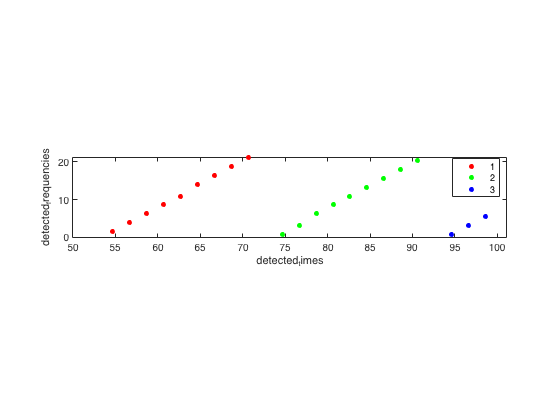

%initialize array to track captured chirps
chirp_tracking.captured_chirps_buffer_size = 128;        %this will be the maximum number of chirps captured when computing the average chirp duration
captured_chirps_buffer_size = chirp_tracking.captured_chirps_buffer_size;
chirp_tracking.num_captured_chirps = 0;
chirp_tracking.captured_chirps = zeros(chirp_tracking.captured_chirps_buffer_size, 2);
chirp_tracking.average_chirp_duration = 0;
chirp_tracking.average_slope = 0;
chirp_tracking.difference_threshold_us = 5;             %this is used as the threshold for detecting if a chirp has previously been detected

%initialize array to track captured frames
frame_tracking.captured_frames_buffer_size = 128;
frame_tracking.num_captured_frames = 0;
frame_tracking.captured_frames = zeros(frame_tracking.captured_frames_buffer_size,7); %duration, number of chirps, average slope, average chirp duration, start time, sampling window count
frame_tracking.average_frame_duration = 0;
frame_tracking.average_chirp_duration = 0;
frame_tracking.average_slope = 0;
frame_tracking.new_frame_threshold_us = 10;             %this is the threshold used for detecting if a chirp is part of the current frame or the next frame

%initialize array to hold the previously measured spectrum
previous_spectogram_points = [];

%initialize counter to keep track of how many full iterations of the while loop
%have occurred
sampling_window_count = 0;

%first compute the sampled chirp within  a frame that the sensing system would receive

%create additional counting variables to aid in the construction of the
%received chirp and frame signals
chirp_sample_index = 1;
max_chirp_sample_index = size(victim.chirp,1);
chirp_samples_left = max_chirp_sample_index;

max_frame_sample_index = victim.frame_params.num_samples_per_frame;
frame_samples_left = max_frame_sample_index;
 
received_sample_index = 1;
max_received_sample_index = spectogram_params.num_ADC_samples_per_spectogram;
received_samples_left = max_received_sample_index;

chirp_count = 0;
frame_count = 0;
while frame_count < frames_to_compute

    

### Assemble the received signal

    received_signal = zeros(spectogram_params.num_ADC_samples_per_spectogram,1);

Average Frame Duration: 33000.014 us

    received_signal_assembled = 0;

Average Chirp Duration: 20.321 us

Average Slope: 1.237 MHz/us

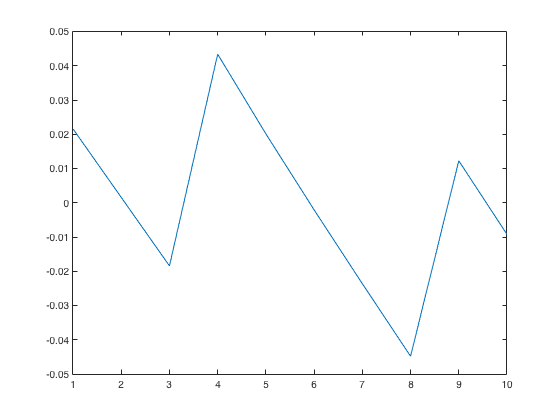

    while ~received_signal_assembled
        %if all of the chirps for a frame have been sent, just send
        %zeros until the end of the current frame
        if chirp_count >= victim.frame_params.num_chirps
            
            if received_samples_left <= frame_samples_left   %done sending chirps, but not end of the frame
                points_to_insert = received_samples_left;
                


                %the following code optimizes the while loop script so that
                %no computations are made when the "victim" is idle and not
                %transmitting. To run the full thing, just comment out the
                %if statement and only leave what is below the if
                %statement.
                if received_samples_left ~= max_received_sample_index
                    received_signal(received_sample_index:received_sample_index + points_to_insert - 1) = zeros(points_to_insert,1);

summary_table = 4×3 table
                              Mean        Variance        MSE    
                            _________    __________    __________

    Detected Times           0.011271      0.034078      0.034193
    Detected Frequencies    -0.013976      0.052398      0.052574
    Computed Slope          -0.003275    9.0047e-05    0.00010049
    Computed Intercept       -0.01167     0.0069428     0.0070575


                    received_signal_assembled = 1;
                else
                    sampling_window_count = sampling_window_count + 1;
                    previous_spectogram_points = [];
                end
                
                received_sample_index = 1;
                received_samples_left = max_received_sample_index;

                frame_samples_left = frame_samples_left - points_to_insert;

                
                if frame_samples_left == 0
                    frame_samples_left = max_frame_sample_index;
                    frame_count = frame_count + 1;
                    chirp_count = 0;
                end

            else                                                %represents the end of the specified frame
                points_to_insert = frame_samples_left;
                
                received_signal(received_sample_index:received_sample_index + points_to_insert - 1) = zeros(points_to_insert,1);

Reshaped Signal: 		 Matches

                
                
                %increment the frame counter and start sending chirps again
                %as new frame has started
                frame_samples_left = max_frame_sample_index;
                frame_count = frame_count + 1;

                chirp_count = 0;

                received_sample_index = received_sample_index + points_to_insert;

Reshaped Signal for fft: 	 Matches

                received_samples_left = max_received_sample_index - received_sample_index + 1;
            end
            
        %the next two statements deal with assembling chirps to be sent out
        elseif received_samples_left >= chirp_samples_left
            points_to_insert = chirp_samples_left;
            received_signal(received_sample_index:received_sample_index + points_to_insert - 1) = victim.chirp(chirp_sample_index:chirp_sample_index + points_to_insert - 1);
            
            chirp_sample_index = 1;

Windowed Signal: 	 Matches

            chirp_samples_left = max_chirp_sample_index;
            chirp_count = chirp_count + 1;
        
            received_sample_index = received_sample_index + points_to_insert;
            received_samples_left = max_received_sample_index - received_sample_index + 1;
            
            frame_samples_left = frame_samples_left - points_to_insert;



Generated Spectogram: 	 Matches

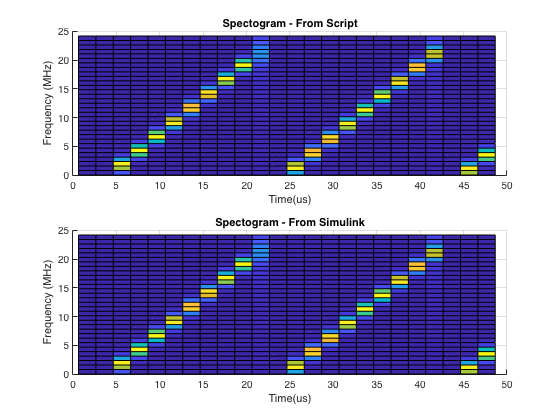

            if received_samples_left <= 0
                received_sample_index = 1;
                received_samples_left = max_received_sample_index;
                received_signal_assembled = 1;
            end
            
        else
            points_to_insert = received_samples_left;
            received_signal(received_sample_index:received_sample_index + points_to_insert - 1) = victim.chirp(chirp_sample_index:chirp_sample_index + points_to_insert - 1);
        
            chirp_sample_index = chirp_sample_index + points_to_insert;
            chirp_samples_left = max_chirp_sample_index - chirp_sample_index + 1;
        
            received_sample_index = 1;
            received_samples_left = max_received_sample_index;
            received_signal_assembled = 1;


            frame_samples_left = frame_samples_left - points_to_insert;
        end
    end



### Reshape the signal and compute the spectogram

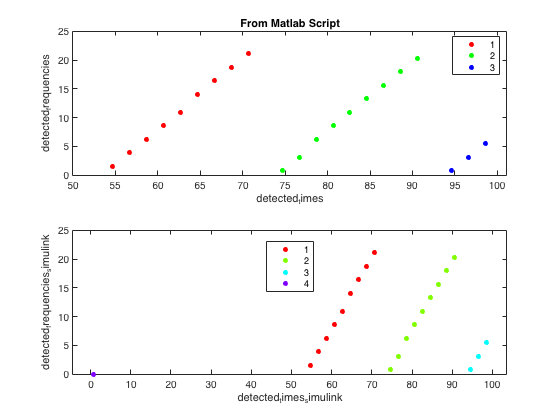

    reshaped_signal = reshape(received_signal,...
        spectogram_params.num_ADC_samples_per_spectogram / spectogram_params.num_freq_spectrum_samples_per_spectogram,...
        spectogram_params.num_freq_spectrum_samples_per_spectogram);
    
    %next, shave off the last few samples so that we get the desired fft size
    reshaped_signal_for_fft = reshaped_signal(1:spectogram_params.fft_size,:);
    

    %window the signal
    windowed_signal = reshaped_signal_for_fft .* spectogram_params.window;
    
    %perform an fft
    generated_spectogram = fft(windowed_signal);
    
    %clip off the negative frequencies;

Detected Times: 	 Matches

    generated_spectogram = generated_spectogram(1:spectogram_params.fft_size/2,:);
    half_fft_size = spectogram_params.fft_size/2; %for SIMULINK model
    
    %plot the spectogram to confirm correct implementation
    plot_params.max_freq = victim.chirp_params.FMCW_sample_rate_Msps/2;
    plot_params.freq_resolution = victim.chirp_params.FMCW_sample_rate_Msps/spectogram_params.fft_size;
    plot_params.frequencies = 0:plot_params.freq_resolution:plot_params.max_freq - plot_params.freq_resolution;

Detected Frequencies: 	 Matches

    plot_params.times = (0: spectogram_params.freq_sampling_period_us : ...
        spectogram_params.num_freq_spectrum_samples_per_spectogram * ...
        spectogram_params.freq_sampling_period_us - spectogram_params.freq_sampling_period_us)...
        + spectogram_params.detected_time_offset;
    
%     imagesc(plot_params.times,plot_params.frequencies, abs(generated_spectogram));
%     subplot(3,1,1);
%     surf(plot_params.times,plot_params.frequencies, abs(generated_spectogram));
%     title_str = sprintf('Spectogram');
%     title(title_str);

Detected Chirps: 	 Matches

%     xlabel('Time(us)')
%     ylabel('Frequency (MHz)')
%     view([0,90.0])

## Detect Peaks in the Spectogram

    peak_detection_params.threshold = 5;
    peak_detection_params.numPeaks = 2;
    spectogram_points = [];  %array to hold the time, freq locations of valid spectogram points
    
    for i = 1:size(generated_spectogram,2)
        [peaks,locations] = findpeaks(abs(generated_spectogram(:,i)),"NPeaks",peak_detection_params.numPeaks);
        locations = locations(peaks > peak_detection_params.threshold);
        if ~isempty(locations)
            locations = [locations.'; i * ones(1,size(locations,1))];
            spectogram_points = [spectogram_points,locations];

Captured Chirps: 	 Matches

        end
    end
    
    %perform clustering on the new spectogram combined with the previous
    %one
    if ~isempty(spectogram_points)

Num Captured Chirps: 	 Matches

        combined_spectogram = [previous_spectogram_points,spectogram_points + [0;spectogram_params.num_freq_spectrum_samples_per_spectogram]];
    else
        combined_spectogram = previous_spectogram_points;
    end
    previous_spectogram_points = spectogram_points;
    

Average Slope: 	 Matches

    if ~isempty(combined_spectogram)
        %DB scan algorithm originally appeared here
        
        
        %compute new times for the combined_spectogram
        plot_params.combined_spectogram_times = (0: spectogram_params.freq_sampling_period_us : ...
            2 * spectogram_params.num_freq_spectrum_samples_per_spectogram * ...

Average Chirp Duration: 	 Matches

            spectogram_params.freq_sampling_period_us - spectogram_params.freq_sampling_period_us) + ...
            spectogram_params.detected_time_offset;
    
        %plot the detected points to confirm that they align
        detected_frequencies = plot_params.frequencies(combined_spectogram(1,:));
        detected_times = plot_params.combined_spectogram_times(combined_spectogram(2,:));

        %moving DB scan to be here so I can use the time and frequency
        %information instead of the indicies
        [idx,corepts] = dbscan([detected_times.',detected_frequencies.'],10,2);
        %[idx,corepts] = dbscan((combined_spectogram).',5,2);

        %plot the clustered detected points
        subplot(3,1,2);

Captured Frames: 	 Matches

        gscatter(detected_times,detected_frequencies,idx);

## Fit a linear model to the computed points to determine slope and intercept

#### Initial Linear Model Computation

 - removed for more practical implementation

#### Revised Linear Model Computation:

link to resourse used to compute linear model: [https://online.stat.psu.edu/stat462/node/132/](https://online.stat.psu.edu/stat462/node/132/) 

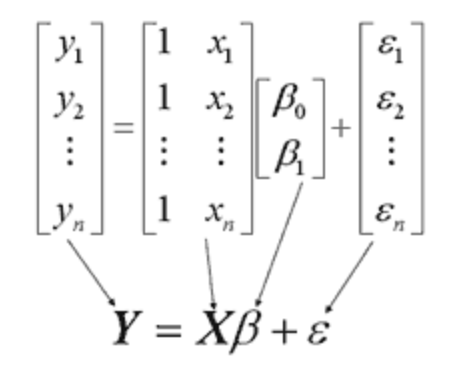

solving for this with out the Epsilon term though


$$\beta = (X^{T}X)^{-1}X^{T}Y$$


        %solve for the linear equation for each cluster provided there are enough
        %points
        max_num_clusters = 10;
        threshold = 7; %originally 15
        detected_chirps = zeros(max(idx),2);

Num Captured Frames: 	 Matches

        for cluster_id = 1:max(idx)
            %solve for linear model using linear algrebra
            %y is frequencies, x is time
            if sum(idx == cluster_id) > threshold
                X = [ones(size(detected_times(idx == cluster_id),2),1),detected_times(idx == cluster_id).'];
                Y = detected_frequencies(idx == cluster_id).';

Average Frame Duration: 	 Matches

                B = inv(X.' * X) * X.' * Y;
                detected_chirps(cluster_id,1:2) = [-B(1)/B(2),B(2)];
                slope = detected_chirps(cluster_id,2);
                intercept = detected_chirps(cluster_id,1);
            end
        end

Average Chirp Duration (frame tracking): 	 Matches

#### Simplified Linear Model

In order to implement this on physical hardware, I also wanted to experiment with implementing using the same number of points and to see how this affects the accuracy

        %Now, we experiment with only taking 15 points to determine the slope and
        %intercept
        num_points_for_linearizing = 15;
        detected_chirps_simplified = zeros(max(idx),2);
        for cluster_id = 1:max(idx)
            if sum(idx == cluster_id) >= num_points_for_linearizing

Average Chirp Slope (frame tracking): 	 Matches

                cluster_times = detected_times(idx == cluster_id);
                cluster_freqs = detected_frequencies(idx == cluster_id);
                X_simplified = [ones(num_points_for_linearizing,1),cluster_times(1:num_points_for_linearizing).'];
                Y_simplified = cluster_freqs(1:num_points_for_linearizing).';
                B_simplified = inv(X_simplified.' * X_simplified) * X_simplified.' * Y_simplified;
                detected_chirps_simplified(cluster_id,1:2) = [-B_simplified(1)/B_simplified(2),B_simplified(2)];
                slope_simplified = detected_chirps_simplified(cluster_id,2);
                intercept_simplified = detected_chirps_simplified(cluster_id,1);
            end
        end
        %detected_chirps_simplified - detected_chirps;
        %shows that decreasing the number of points affected the computed intercept
        %point

### Compute the average chirp period and average slope

        detected_chirps = detected_chirps + [spectogram_params.num_freq_spectrum_samples_per_spectogram * ...
                    spectogram_params.freq_sampling_period_us * (sampling_window_count - 1), 0];
        for i = 1:size(detected_chirps,1)
            if detected_chirps(i,2) ~= 0 && chirp_tracking.num_captured_chirps < chirp_tracking.captured_chirps_buffer_size
                if chirp_tracking.num_captured_chirps == 0 %if the captured chirps buffer is empty (i.e: first chirp detected or first chirp in a frame)
                    chirp_tracking.captured_chirps(1,:) = detected_chirps(i,:);
                    chirp_tracking.num_captured_chirps = chirp_tracking.num_captured_chirps + 1;
                    Debugger = debugger_save_detection_points(Debugger,frame_tracking,chirp_tracking,spectogram_params,victim,...
                                                            detected_times,detected_frequencies,idx,...
                                                            detected_chirps, i, sampling_window_count);                
                elseif all(abs(chirp_tracking.captured_chirps - detected_chirps(i,1)) > chirp_tracking.average_chirp_duration / 2,'all')
                    if chirp_tracking.num_captured_chirps >= 2
                        duration_difference_from_avg = abs(detected_chirps(i,1) - chirp_tracking.captured_chirps(chirp_tracking.num_captured_chirps,1) - chirp_tracking.average_chirp_duration);
                        if duration_difference_from_avg >= frame_tracking.new_frame_threshold_us %declare as part of a new frame
                            %increment the frame counter
                            frame_tracking.num_captured_frames = frame_tracking.num_captured_frames + 1;
                            %save the duration, number of chirps, average slope, average chirp duration, start time, and sampling window count
                            frame_tracking.captured_frames(frame_tracking.num_captured_frames,1) = detected_chirps(i,1) - chirp_tracking.captured_chirps(1,1);  % duration
                            frame_tracking.captured_frames(frame_tracking.num_captured_frames,2) = chirp_tracking.num_captured_chirps;                          % number of chirps
                            frame_tracking.captured_frames(frame_tracking.num_captured_frames,3) = chirp_tracking.average_slope;                                % average slope
                            frame_tracking.captured_frames(frame_tracking.num_captured_frames,4) = chirp_tracking.average_chirp_duration;                       % average_chirp_duration
                            frame_tracking.captured_frames(frame_tracking.num_captured_frames,5) = chirp_tracking.captured_chirps(1,1);
                            frame_tracking.captured_frames(frame_tracking.num_captured_frames,6) = sampling_window_count;

                            %reset the chirp tracking
                            chirp_tracking.num_captured_chirps = 0;
                            chirp_tracking.captured_chirps = zeros(chirp_tracking.captured_chirps_buffer_size, 2);
                            chirp_tracking.average_chirp_duration = 0;
                            chirp_tracking.average_slope = 0;
                            
                            %reset sampling window - not implemented yet
                            frame_tracking.average_frame_duration = sum(frame_tracking.captured_frames(:,1)) / frame_tracking.num_captured_frames;
                            
                            %compute the overall averages for chirp slope
                            %and duration
                            frame_tracking.average_chirp_duration =  ...
                                sum(frame_tracking.captured_frames(:,4) .* (frame_tracking.captured_frames(:,2) - 1))/ ...
                                sum((frame_tracking.captured_frames(frame_tracking.captured_frames(:,2) ~=0,2) - 1));
                            frame_tracking.average_slope = ...
                                sum(frame_tracking.captured_frames(:,3) .* (frame_tracking.captured_frames(:,2) - 1))/ ...
                                sum((frame_tracking.captured_frames(frame_tracking.captured_frames(:,2) ~=0,2) - 1));

                            %compute the predicted time for the next chirp
                            %to occur on.
                            frame_tracking.captured_frames(frame_tracking.num_captured_frames,7) = ...
                                        detected_chirps(i,1) + frame_tracking.average_frame_duration;
                        end
                    end
                    chirp_tracking.captured_chirps(chirp_tracking.num_captured_chirps + 1,:) = detected_chirps(i,:);
                    chirp_tracking.num_captured_chirps = chirp_tracking.num_captured_chirps + 1;

                    Debugger = debugger_save_detection_points(Debugger,frame_tracking,chirp_tracking,spectogram_params,victim,...
                                                            detected_times,detected_frequencies,idx,...
                                                            detected_chirps, i, sampling_window_count);
                end
                chirp_tracking.average_slope = sum(chirp_tracking.captured_chirps(1:chirp_tracking.num_captured_chirps,2))/ double(chirp_tracking.num_captured_chirps);
                if chirp_tracking.num_captured_chirps >= 2
                    chirp_tracking.average_chirp_duration = (chirp_tracking.captured_chirps(chirp_tracking.num_captured_chirps,1) - chirp_tracking.captured_chirps(1,1))/double(chirp_tracking.num_captured_chirps - 1);
                end
            end
        end
    end
    sampling_window_count = sampling_window_count + 1;
end

%print out the relevant information
fprintf("Average Frame Duration: %5.3f us",frame_tracking.average_frame_duration);
fprintf("Average Chirp Duration: %3.3f us",frame_tracking.average_chirp_duration);
fprintf("Average Slope: %1.3f MHz/us",frame_tracking.average_slope);

%compare the predicted frame start times with the actual frame start times
actual_frame_start_times = (2:frames_to_compute +1).' * victim.frame_params.cycle_time_ms * 1e3 ... 
                                + victim.chirp_params.idle_time_us;
predicted_start_time_errors = frame_tracking.captured_frames(1:frame_tracking.num_captured_frames,7) ...
                                - actual_frame_start_times;

clf;
plot(predicted_start_time_errors);

## Run the Debugger if enabled

if Debugger.enabled
    Debugger = debugger_compute_errors(Debugger,victim);
    [Debugger,summary_table] = debugger_summarize_errors(Debugger);
    summary_table
end

## Check simulated values to make sure that they are the same as matlab computed values

### Initialize the Simulink model and run it

open_system('SensingSubsystem_revB');
stop_time = sampling_window_count * spectogram_params.num_ADC_samples_per_spectogram / victim.waveform_params.sample_rate_Hz;
set_param('SensingSubsystem_revB','StopTime','stop_time');
warning_to_suppress_id = 'Coder:MATLAB:illConditionedMatrix';
warning('off',warning_to_suppress_id);
out = sim('SensingSubsystem_revB','SimulationMode','accelerator','SaveOutput','on');

### Reshaped Signal

%check a few chirps later to ensure that no timing errors or drift
reshaped_signal_simulink = out.reshaped_signal(:,:,2);
compare = all(reshaped_signal == reshaped_signal_simulink,'all');

if compare
    fprintf("Reshaped Signal: \t\t Matches")
else
    fprintf("Reshaped Signal: \t\t Does Not Match")
end

### Reshaped Signal - for fft

reshaped_signal_for_fft_simulink = out.reshaped_signal_for_fft(:,:,2);
compare = all(reshaped_signal_for_fft == reshaped_signal_for_fft_simulink,'all');

if compare
    fprintf("Reshaped Signal for fft: \t Matches")
else
    fprintf("Reshaped Signal for fft: \t Does Not Match")
end

### Windowed Signal

windowed_signal_simulink = out.windowed_signal(:,:,2);
compare = all(windowed_signal == windowed_signal_simulink);
if compare
    fprintf("Windowed Signal: \t Matches")
else
    fprintf("Windowed Signal: \t Does Not Match")
end

### Generated Spectogram

generated_spectogram_simulink = out.generated_spectogram(:,:,2);
compare = all(abs(generated_spectogram - generated_spectogram_simulink) <= 1e-10,'all');
if compare
    fprintf("Generated Spectogram: \t Matches")
else
    fprintf("Generated Spectogram: \t Does Not Match")
end
%imagesc(plot_params.times,plot_params.frequencies, abs(generated_spectogram));
clf;
subplot(2,1,1)
surf(plot_params.times,plot_params.frequencies, abs(generated_spectogram));
title_str = sprintf('Spectogram - From Script');
title(title_str);
xlabel('Time(us)')
ylabel('Frequency (MHz)')
view([0,90.0])
subplot(2,1,2)
surf(plot_params.times,plot_params.frequencies, abs(generated_spectogram_simulink));
title_str = sprintf('Spectogram - From Simulink');
title(title_str);
xlabel('Time(us)')
ylabel('Frequency (MHz)')
view([0,90.0])

### Detect Peaks

%obtain the detected times and frequencies
detected_times_simulink = out.detected_times(2,:);
detected_frequencies_simulink = out.detected_frequencies(2,:);
idx_simulink = out.idx(:,:,2);

clf;
subplot(2,1,1);
gscatter(detected_times,detected_frequencies,idx);
title('From Matlab Script')
subplot(2,1,2);
title('From Simulink')
gscatter(detected_times_simulink,detected_frequencies_simulink,idx_simulink);
%compare detected chirps and output
compare = all(detected_times_simulink(detected_frequencies_simulink > 0) == detected_times); %frequencies won't be zero, time could be zero
if compare
    fprintf("Detected Times: \t Matches")
else
    fprintf("Detected Times: \t Does Not Match")
end

compare = all(detected_frequencies_simulink(detected_frequencies_simulink > 0) == detected_frequencies);
if compare
    fprintf("Detected Frequencies: \t Matches")
else
    fprintf("Detected Frequencies: \t Does Not Match")
end

### Verifing detected chirp observations

detected_chirps_simulink = out.detected_chirps(:,:,2);

compare = (detected_chirps_simulink(detected_chirps_simulink(:,2) ~=0, :) - detected_chirps(detected_chirps(:,2) ~=0, :)) < 1e-10;
if compare
    fprintf("Detected Chirps: \t Matches")
else
    fprintf("Detected Chirps: \t Does Not Match")
end

### Verifing the computed slope and duration

captured_chirps_simulink = out.chirp_tracking_captured_chirps(:,:,2);
num_captured_chirps_simulink = out.chirp_tracking_chirp_count(2);
average_slope_simulink = out.chirp_tracking_slope(2);
average_chirp_duration_simulink = out.chirp_tracking_duration(2);

compare = all(abs(captured_chirps_simulink - chirp_tracking.captured_chirps) < 1e-10);
if compare
    fprintf("Captured Chirps: \t Matches")
else
    fprintf("Captured Chirps: \t Does Not Match")
end
compare = (num_captured_chirps_simulink == chirp_tracking.num_captured_chirps);
if compare
    fprintf("Num Captured Chirps: \t Matches")
else
    fprintf("Num Captured Chirps: \t Does Not Match")
end
compare = (abs(average_slope_simulink - chirp_tracking.average_slope) < 1e-10);
if compare
    fprintf("Average Slope: \t Matches")
else
    fprintf("Average Slope: \t Does Not Match")
end

compare = (abs(average_chirp_duration_simulink - chirp_tracking.average_chirp_duration) < 1e-10);
if compare
    fprintf("Average Chirp Duration: \t Matches")
else
    fprintf("Average Chirp Duration: \t Does Not Match")
end

### Verifing the computed frame information

frame_tracking_captured_frames_simulink = out.frame_tracking_frames(:,:,2);
frame_tracking_num_captured_frames_simulink = out.frame_tracking_frame_count(2);
frame_tracking_average_frame_duration_simulink = out.frame_tracking_frame_duration(2);
frame_tracking_average_chirp_duration_simulink = out.frame_tracking_chirp_duration(2);
frame_tracking_average_slope_simulink = out.frame_tracking_slope(2);

compare = all(abs(frame_tracking_captured_frames_simulink - frame_tracking.captured_frames) < 1e-10);
if compare
    fprintf("Captured Frames: \t Matches")
else
    fprintf("Captured Frames: \t Does Not Match")
end
compare = (frame_tracking_num_captured_frames_simulink == frame_tracking.num_captured_frames);
if compare
    fprintf("Num Captured Frames: \t Matches")
else
    fprintf("Num Captured Frames: \t Does Not Match")
end
compare = (abs(frame_tracking_average_frame_duration_simulink - frame_tracking.average_frame_duration) < 1e-10);
if compare
    fprintf("Average Frame Duration: \t Matches")
else
    fprintf("Average Frame Duration: \t Does Not Match")
end
compare = (abs(frame_tracking_average_chirp_duration_simulink - frame_tracking.average_chirp_duration) < 1e-10);
if compare
    fprintf("Average Chirp Duration (frame tracking): \t Matches")
else
    fprintf("Average Chirp Duration (frame tracking): \t Does Not Match")
end
compare = (abs(frame_tracking_average_slope_simulink - frame_tracking.average_slope) < 1e-10);
if compare
    fprintf("Average Chirp Slope (frame tracking): \t Matches")
else
    fprintf("Average Chirp Slope (frame tracking): \t Does Not Match")
end

### Debugger Functions

function Debugger_updated = debugger_save_detection_points(Debugger,frame_tracking,chirp_tracking,spectogram_params,victim,...
                                                            detected_times,detected_frequencies,idx,...
                                                            detected_chirps, detected_chirp_index, sampling_window_count)
%{
    Purpose: updates the debugger object (if enabled)
    Inputs:
        Debugger - the previous debugger object
        frame_tracking - the current frame_tracking object
        chirp_tracking - the current chirp_tracking object
        spectogram_params - the spectogram_params structure containing
            spectogram parameter settings
        victim - the victim object containing relevant frame and chirp
            parameters
        detected_times - the current detected_times_array
        detected_frequencies - the current detected_frequencies array
        idx - the idx output from the clustering algorithm
        detected_chirps - the current detected_chirps array
        detected_chirp_index - the cluster I.D (in the idx) for the whose chirp whose values are being stored
        sampling_window_count - the current sampling window count
    Outputs: 
        Debugger_updated - the updated debugger object
%}
    if Debugger.enabled
         
        debugger_index = (frame_tracking.num_captured_frames) * victim.frame_params.num_chirps + chirp_tracking.num_captured_chirps;
        timing_offset = spectogram_params.num_freq_spectrum_samples_per_spectogram * ...
                    spectogram_params.freq_sampling_period_us * (sampling_window_count - 1);

        %save the detected times
        Debugger.detected_times(debugger_index,1: 2 + size(idx(idx == detected_chirp_index),1)) = ...
            [frame_tracking.num_captured_frames + 1,chirp_tracking.num_captured_chirps, ...
            timing_offset + detected_times(idx == detected_chirp_index)];
        %save the detected frequencies
        Debugger.detected_frequencies(debugger_index,1:2 + size(idx(idx == detected_chirp_index),1)) = ...
            [frame_tracking.num_captured_frames + 1,chirp_tracking.num_captured_chirps, detected_frequencies(idx == detected_chirp_index)];

        Debugger.detected_chirp_slopes(debugger_index,:) = ...
            [frame_tracking.num_captured_frames + 1,chirp_tracking.num_captured_chirps,detected_chirps(detected_chirp_index,2)];
        Debugger.detected_chirp_intercepts(debugger_index,:) = ...
            [frame_tracking.num_captured_frames + 1,chirp_tracking.num_captured_chirps,detected_chirps(detected_chirp_index,1)];
    end
    Debugger_updated = Debugger;
end

function Debugger_updated = debugger_compute_errors(Debugger,victim)
%{
    Purpose: compares the measured values with what the actual values
    should be
    Inputs:
        Debugger - the previous debugger object
        victim - the victim object containing relevant frame and chirp
            parameters
    Outputs: 
        Debugger_updated - the updated debugger object
%}
    if Debugger.enabled
        %update the sizes of the error trackers as the size may have
        %changed slightly when computing:
        Debugger.detected_times_errors = zeros(size(Debugger.detected_times));
        Debugger.detected_frequencies_errors = zeros(size(Debugger.detected_frequencies));
        Debugger.detected_chirp_slopes_errors = zeros(size(Debugger.detected_chirp_slopes));
        Debugger.detected_chirp_intercepts_errors = zeros(size(Debugger.detected_chirp_intercepts));
        
    %compute the errors
        true_chirp_intercepts = ...
            (Debugger.detected_chirp_intercepts(:,1) - 1) * victim.frame_params.cycle_time_ms * 1e3 +...
            (Debugger.detected_chirp_intercepts(:,2) - 1) * victim.chirp_params.cycle_period_us + ...
            victim.chirp_params.idle_time_us;

        %intercept errors
        Debugger.detected_chirp_intercepts_errors(:,1:2) = Debugger.detected_chirp_intercepts(:,1:2);
        Debugger.detected_chirp_intercepts_errors(:,3) = Debugger.detected_chirp_intercepts(:,3) - true_chirp_intercepts; 

        %slope errors
        Debugger.detected_chirp_slopes_errors(:,1:2) = Debugger.detected_chirp_slopes(:,1:2);
        Debugger.detected_chirp_slopes_errors(:,3) = Debugger.detected_chirp_slopes(:,3) - victim.chirp_params.slope_MHz_us;

        %error for time points
        Debugger.detected_times_errors(:,1:2) = Debugger.detected_times(:,1:2);
        for i = 1:size(Debugger.detected_times,1)
            num_detected_times = sum(Debugger.detected_times(i,3:end) ~= 0);
            true_times = (Debugger.detected_frequencies(i,3:num_detected_times + 2) / ...
                victim.chirp_params.slope_MHz_us) + true_chirp_intercepts(i);
            Debugger.detected_times_errors(i,3:num_detected_times + 2) = ...
                Debugger.detected_times(i,3:num_detected_times + 2) - true_times;
        end
        
        %error for frequency points
        Debugger.detected_frequencies_errors(:,1:2) = Debugger.detected_frequencies(:,1:2);
        for i = 1:size(Debugger.detected_frequencies,1)
            num_detected_frequencies = sum(Debugger.detected_frequencies(i,3:end) ~= 0);
            true_frequencies = victim.chirp_params.slope_MHz_us * ...
                (Debugger.detected_times(i,3:num_detected_frequencies + 2) - true_chirp_intercepts(i));
            Debugger.detected_frequencies_errors(i,3:num_detected_frequencies + 2) = ...
                Debugger.detected_frequencies(i,3:num_detected_frequencies + 2) - true_frequencies;
        end

    end
    Debugger_updated = Debugger;
end

function [Debugger_updated,summary_table] = debugger_summarize_errors(Debugger)
    %{
        Purpose: computes the sample mean, sample variance, and mean
        squared error for the slope, intercept, timing, and frequency
        errors
    %}
    %chirp intercepts
    [mean,variance,MSE] = compute_summary_statistics(...
        Debugger.detected_chirp_intercepts_errors, Debugger.detected_chirp_intercepts);
    Debugger.detected_chirp_intercepts_errors_summary(1:3) = [mean,variance,MSE];
    %slope
    [mean,variance,MSE] = compute_summary_statistics(...
        Debugger.detected_chirp_slopes_errors, Debugger.detected_chirp_slopes);
    Debugger.detected_chirp_slopes_errors_summary(1:3) = [mean,variance,MSE];
     %frequency measurement
    [mean,variance,MSE] = compute_summary_statistics(...
        Debugger.detected_frequencies_errors, Debugger.detected_frequencies);
    Debugger.detected_frequencies_errors_summary(1:3) = [mean,variance,MSE];
     %time measurement
    [mean,variance,MSE] = compute_summary_statistics(...
        Debugger.detected_times_errors, Debugger.detected_times);
    Debugger.detected_times_errors_summary(1:3) = [mean,variance,MSE];

    %output the table as well
    Debugger_updated = Debugger;
    summary_table = array2table( ...
        [Debugger.detected_times_errors_summary;...
        Debugger.detected_frequencies_errors_summary;...
        Debugger.detected_chirp_slopes_errors_summary;...
        Debugger.detected_chirp_intercepts_errors_summary], ...
        "VariableNames",[ "Mean","Variance","MSE"], ...
        "RowNames",["Detected Times","Detected Frequencies","Computed Slope","Computed Intercept"]);
end

function [sample_mean,sample_variance,MSE] = compute_summary_statistics(errors_array, debugger_array)
    %{
        Purpose: computes the sample mean, sample variance, and mean
            squared error for the various errors captured by the debugger
        Inputs: 
            Errors_array: an array containing the errors computed from the
                debugger
            Debugger_array: the array containing the measured values from
                the debugger
    %}
    valid_intercepts = debugger_array ~= 0;
    valid_intercepts(:,1:2) = 0;
    sample_mean = ...
        sum(errors_array(valid_intercepts),'all') /...
        sum(valid_intercepts,'all');
    sample_variance = ...
        sum((errors_array(valid_intercepts) - sample_mean).^2,'all') /...
        (sum(valid_intercepts,'all')-1);
    MSE = ...
        sum(errors_array(valid_intercepts).^2,'all') /...
        (sum(valid_intercepts,'all'));
end